准备数据集 灰度图和Mask

fluo = rgb2gray(imread('001-bf.jpg'));
fluo = fluo(1:1500,2000:4500);
imagesc(fluo)
imwrite(fluo,'image_001.jpg')

mask = im2bw(imread('001-fluo.jpg'),maps,0.165);
mask = mask(1:1500,2000:4500);
imshow(mask);
imwrite(mask,'image_labeled_001.png')

fluo = rgb2gray(imread('002-bf.jpg'));
fluo = fluo(1:2000,2000:end)
imagesc(fluo)
imwrite(fluo,'image_002.jpg')

mask = im2bw(imread('002-fluo.jpg'),maps,0.165);
mask = mask(1:2000,2000:end);
imshow(mask);
imwrite(mask,'image_labeled_002.png')

fluo = rgb2gray(imread('003-bf.jpg'));
fluo = fluo(600:end,1200:3400)

imagesc(fluo)
axis tight equal
imwrite(fluo,'image_003.jpg')

mask = im2bw(imread('003-fluo.jpg'),maps,0.165);
mask = mask(600:end,1200:3400);
imshow(mask);
imwrite(mask,'image_labeled_003.png')

fluo = imread('004.tif');
fluo = fluo(1:3400,:,:);
imagesc(fluo)
imwrite(fluo,'image_004.jpg')

mask = im2bw(imread('004_g.tif'),0.13);
mask = mask(1:3400,:);
imshow(mask);
imwrite(mask,'image_labeled_004.png')

创建和训练Unet

% 创建数据集和Unet从这里开始 % 基于灰度图的训练
dataFolder  = fullfile('./data4unet/');

imageDir = fullfile(dataFolder,'trainingImages');
labelDir = fullfile(dataFolder,'trainingLabels');

classNames = ["fluo","background"];
labelIDs   = [1 0]

labelIDs =      1     0



imds = imageDatastore(imageDir);
pxds = pixelLabelDatastore(labelDir,classNames,labelIDs);

% 数据增强
augmenter = imageDataAugmenter('RandXReflection',true,'RandYReflection',true,...
    'RandXTranslation', [-10 10], 'RandYTranslation', [-20 20], 'RandRotation', [-180 180],...
    'RandYshear',[-30 30],'RandXshear',[0 30]);

dsTrain = randomPatchExtractionDatastore(imds,pxds,[256 256],'PatchesPerImage',80,'DataAugmentation',augmenter);

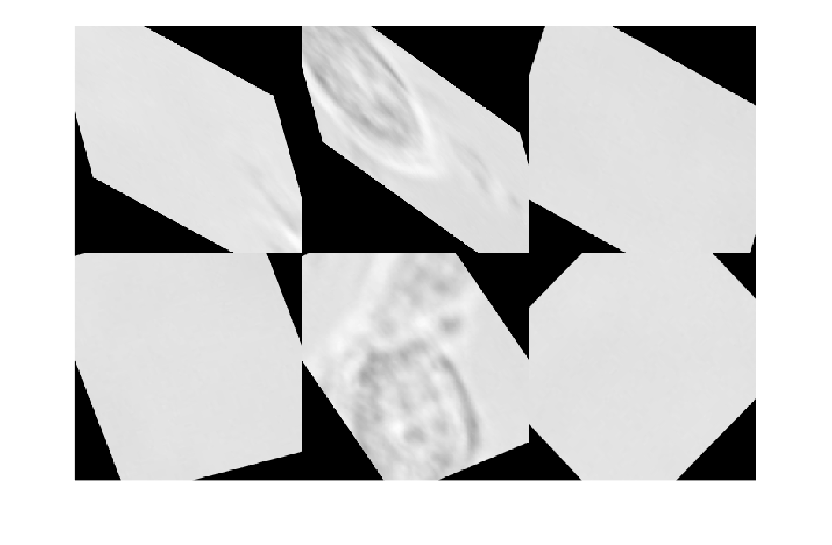

ims = dsTrain.preview();
montage(ims{1:6,1}) % to visualize 6 images

imageSize = [256 256];
numClasses = 2;
lgraph = unetLayers(imageSize, numClasses);
% disp(lgraph.Layers);

% Select Training Options
initialLearningRate = 0.05;
maxEpochs = 3000;  
minibatchSize = 2;
l2reg = 0.0001;

options = trainingOptions('sgdm',...
    'InitialLearnRate',initialLearningRate, ...
    'Momentum',0.9,...
    'L2Regularization',l2reg,...
    'MaxEpochs',maxEpochs,...
    'MiniBatchSize',minibatchSize,...
    'LearnRateSchedule','piecewise',...    
    'Shuffle','every-epoch',...
    'GradientThresholdMethod','l2norm',...
    'GradientThreshold',0.05, ...
    'Plots','training-progress', ...
    'VerboseFrequency',200);

doTraining = true; 
if doTraining
    [net,info] = trainNetwork(dsTrain,lgraph,options);
    modelDateTime = string(datetime('now','Format',"yyyy-MM-dd-HH-mm-ss"));
    save(strcat("Unet",modelDateTime,"-Epoch-",num2str(maxEpochs),".mat"),'net');
end

 加载神经网络 并 测试

data = load('Unet2022.mat');
net = data.net;
net.Layers

ans =   具有以下层的 58×1 Layer 数组:

     1   'ImageInputLayer'                      图像输入                       256×256×1 图像: 'zerocenter' 归一化
     2   'Encoder-Stage-1-Conv-1'               卷积                          64 3×3×1 卷积: 步幅 [1  1]，填充 'same'
     3   'Encoder-Stage-1-ReLU-1'               ReLU                         ReLU
     4   'Encoder-Stage-1-Conv-2'               卷积                          64 3×3×64 卷积: 步幅 [1  1]，填充 'same'
     5   'Encoder-Stage-1-ReLU-2'               ReLU                         ReLU
     6   'Encoder-Stage-1-MaxPool'              最大池化                       2×2 最大池化: 步幅 [2  2]，填充 [0  0  0  0]
     7   'Encoder-Stage-2-Conv-1'               卷积                          128 3×3×64 卷积: 步幅 [1  1]，填充 'same'
     8   'Encoder-Stage-2-ReLU-1'               ReLU                         ReLU
     9   'Encoder-Stage-2-Conv-2'               卷积                          128 3×3×128 卷积: 步幅 [1  

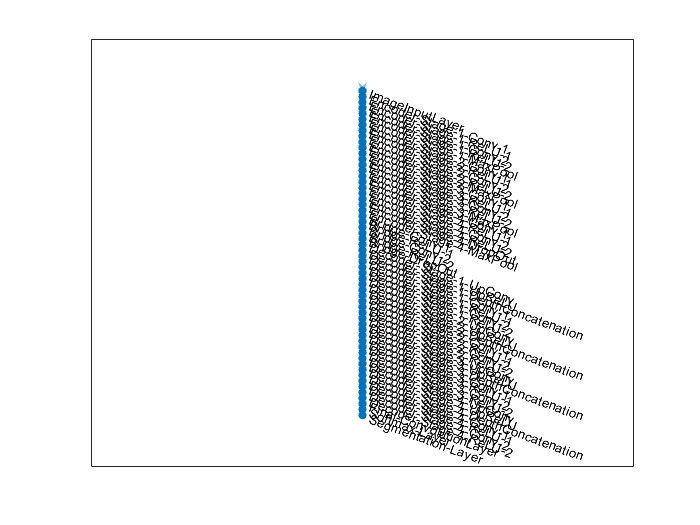

lgraph = layerGraph(net.Layers);
figure
plot(lgraph);

% 指定传入semanticseg函数内的矩阵大小，必须为256的倍数
% 读入需要处理的图片
originalPicture =  rgb2gray(imread('001-bf.jpg'));
sampleSize = 256;
[oriRow,oriCol] = size(originalPicture);
rowNumber = fix(oriRow/sampleSize);
colNumber = fix(oriCol/sampleSize);
for rowCount = 1:rowNumber+1;
for colCount = 1:colNumber+1;
if colCount == colNumber+1 && rowCount == rowNumber+1;
samplePicutre = originalPicture(oriRow-sampleSize+1:oriRow,oriCol-sampleSize+1:oriCol);
patch = semanticseg(samplePicutre, net);
finalPatch(oriRow-sampleSize+1:oriRow,oriCol-sampleSize+1:oriCol) = patch;
elseif colCount == colNumber+1
samplePicutre = originalPicture((sampleSize*(rowCount-1)+1):sampleSize*(rowCount),oriCol-sampleSize+1:oriCol);
patch = semanticseg(samplePicutre, net);
finalPatch((sampleSize*(rowCount-1)+1):sampleSize*(rowCount),oriCol-sampleSize+1:oriCol) = patch;
elseif rowCount == rowNumber+1
samplePicutre = originalPicture(oriRow-sampleSize+1:oriRow,(sampleSize*(colCount-1)+1):sampleSize*(colCount));
patch = semanticseg(samplePicutre, net);
finalPatch(oriRow-sampleSize+1:oriRow,(sampleSize*(colCount-1)+1):sampleSize*(colCount)) = patch;
else
samplePicutre = originalPicture((sampleSize*(rowCount-1)+1):sampleSize*(rowCount),(sampleSize*(colCount-1)+1):sampleSize*(colCount));
patch = semanticseg(samplePicutre, net);
finalPatch((sampleSize*(rowCount-1)+1):sampleSize*(rowCount),(sampleSize*(colCount-1)+1):sampleSize*(colCount)) = patch; 
end
end
end
finalPatch;
finalPicture = labeloverlay(originalPicture, finalPatch);
figure
imshow(finalPicture)


finalMaskBW = double(finalPatch)-2;
finalMaskBW = abs(finalMaskBW);
finalMaskBW = imfill(finalMaskBW,"holes");
finalMaskBW = bwareaopen(finalMaskBW,2200); % 移除面积小于2500的

[rgbMask,numObj] = BW2rgbMask(finalMaskBW);
imshow(rgbMask)

% 细胞个数
numObj

% PSNR 计算
ref = imread('001-fluo.jpg'); % RGB 绿色图
imshow(ref);

PSNR = psnr(rgbMask,ref)

function [rgbMask,numObj] = BW2rgbMask(BW)
d = bwdist(~BW);

d = imcomplement(d);

d = imhmin(d,1);

% Calculate the watershed transform of d
fluoSep = watershed(d);
% imshow(fluoSep,[])

% Create RGB Mask
fluoSep(~BW) = 0;

hts1 = regionprops("table",fluoSep,"MajorAxisLength");
numObj = height(hts1);

% number_of_labels 
n = max(fluoSep(:));

a = 0.00;
b = 0.49;
c = 0.1;

map = [ones(n,1)*a ones(n,1)*b ones(n,1)*c];

rgbMask = label2rgb(fluoSep,map,'k');
end